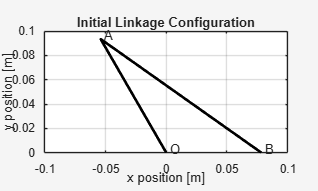

%%%%%%%%%%%%%%%%%%%%%%% PARAMETER DEFINITIONS %%%%%%%%%%%%%%%%%%%%%%%%%%%

p.r_1 = 0.315; % Fixed pivot spacing OC [m]
p.r_2 = 0.108; % Crank length OA [m]
p.r_3 = 0.162; % Coupler length AB [m]
p.r_4 = 0.324; % Piston rod length BD [m]
theta2 = deg2rad(120);
qGuess = [0.08; deg2rad(305)];
p.m_2 = 1.0; % crank OA mass [kg]
p.m_3 = 1.5; % couple AB mass [kg]
p.m_4 = 2.0; % piston rod mass [kg]
p.I_2 = p.m_2 * p.r_2^2 / 12; % mass moment of inertia for crank OA [kg*m^2]
p.I_3 = p.m_3 * p.r_3^2 / 12; % mass moment of inertia for coupler AB [kg*m^2]

%%%%%%%%%%%%%%%% SOLVING FOR THE INITIAL CONFIGURATION %%%%%%%%%%%%%%%%%%

options = optimoptions('fsolve',...
    'SpecifyObjectiveGradient',true,...
    'Display','none');

[q0,ph10,exitflag,output] = fsolve(...
    @(q) crankPistonResidual(q,theta2,p),...
    qGuess,options);

E0 = ph10.'*ph10;
ep0 = norm(ph10,2);

O = [0; 0]; 
A = p.r_2*[cos(theta2);sin(theta2)];
B = [q0(1);0];

d = 0.003; % Label offset [m]

%%%%%%%%%%%%%%%%%%%%%%%%%%%% LAB 5A.4.3 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Figure showing the initial linkage configuration in xy coordinate system.
figure
theme(figure, "light")
plot([O(1) A(1) B(1)], [O(2) A(2) B(2)], 'k-', 'LineWidth', 2);
text(O(1)+d,O(2)+d,'O');
text(A(1)+d,A(2)+d,'A');
text(B(1)+d,B(2)+d,'B');
hold off
grid on
axis equal
xlim([-0.1 0.1])
ylim([0 0.1])
xlabel('x position [m]');
ylabel('y position [m]');
title('Initial Linkage Configuration');


%%%%%%%%%%%%%%%%%%%%%%%%%%%% LAB 5A.4.5 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Defining theta2dot and theta2ddot for use in kinematics function
theta2dot = -10*2*pi/60; % crank speed = 10 rpm clockwise --> negative [rad/s]
theta2ddot = 0; % constant speed

% Kinematics function returning values for initial configuration
[q0dot,q0ddot,J0,bv0,ba0] = crankPistonKinematics(theta2,theta2dot,theta2ddot,q0,p);

% Function returning initial configuration values for the position and
% velocity of points A and B 
[A0,B0,vA0,vB0] = crankPistonPoints(theta2,theta2dot,q0,q0dot,p);

% Using rigid-body relative-velocity equation as an independent check
r_BA = [B0 - A0 ; 0];
vrel = [vB0 - vA0; 0];
theta3dotCheck = (r_BA(1)*vrel(2) - r_BA(2)*vrel(1)) / dot(r_BA(1:2), r_BA(1:2));
vBCheck = vA0 + theta3dotCheck * [-r_BA(2); r_BA(1)]

vBCheck =     0.0580
         0


velocityError = norm(vB0 - vBCheck)

velocityError = 6.9389e-18


%%%%%%%%%%%%%%%%%%%%%%%%%%%% LAB 5A.4.6 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Completing one full clockwise crank revolution. At each angle, fsolve -->
% q, J\bv --> qdot, partial sums --> A, B, vA, vB. Each fsolve starts from
% the previous answer. 

N = 361;
theta2_sweep = theta2 + linspace(0, -2*pi, N);

exitflag_stored = zeros(1,N);
q_stored = zeros(2,N); % [r_ob ; theta3] for every angle
qdot_stored = zeros(2,N); % [r_ob_dot ; theta3dot] for every angle
A_stored = zeros(2,N); % [x ; y] for A for every angle
B_stored = zeros(2,N); % [x ; y] for B for every angle
vA_stored = zeros(2,N); % [vA(x) ; vA(y)] for every angle
vB_stored = zeros(2,N); % [vB(x) ; vB(y)] for every angle

qPrev = q0;

for k = 1:N
    th2 = theta2_sweep(k);

    [qk,~,flag] = fsolve(@(q) crankPistonResidual(q,th2,p), qPrev, options);

    qdotk = crankPistonKinematics(th2,theta2dot,theta2ddot,qk,p);

    [Ak,Bk,vAk,vBk] = crankPistonPoints(th2,theta2dot,qk,qdotk,p);

    exitflag_stored(k) = flag;
    q_stored(:,k) = qk;
    qdot_stored(:,k) = qdotk;
    A_stored(:,k) = Ak;
    B_stored(:,k) = Bk;
    vA_stored(:,k) = vAk;
    vB_stored(:,k) = vBk;
    qPrev = qk;

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%% LAB 5A.4.7 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Summarizing the position sweep: creating one table with the initial
% values of q, qdot, theta2, and theta2dot and one two-tile figure showing
% the two components of q and qdot against theta2.

initialValues = table(theta2,theta2dot,q0(1),q0(2),q0dot(1),q0dot(2), ...
    'VariableNames',{'theta2 [rad]','theta2dot [rad/s]','r_ob [m]','theta3 [rad]','r_ob_dot [m/s]','theta3dot [rad/s]'});

initialValues

initialValues = 1×6 table
    theta2 [rad]    theta2dot [rad/s]    r_ob [m]    theta3 [rad]    r_ob_dot [m/s]    theta3dot [rad/s]
    ____________    _________________    ________    ____________    ______________    _________________

       2.0944            -1.0472         0.078273       5.6677          0.057959           -0.42752     

	Get insights using Copilot


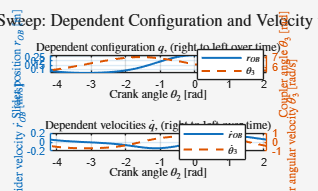


figure
theme(gcf, "light")
tl = tiledlayout(2,1);
title(tl, 'Part A Position Sweep: Dependent Configuration and Velocity vs. Crank Angle', 'Interpreter', 'latex')

nexttile
yyaxis left
plot(theta2_sweep, q_stored(1,:), '-', 'LineWidth', 1.5)
ylabel('Slider position $r_{OB}$ [m]', 'Interpreter', 'latex')
yyaxis right
plot(theta2_sweep, q_stored(2,:), '--', 'LineWidth', 1.5)
ylabel('Coupler angle $\theta_3$ [rad]', 'Interpreter', 'latex')
xlabel('Crank angle $\theta_2$ [rad]', 'Interpreter', 'latex')
legend('$r_{OB}$', '$\theta_3$', 'Interpreter', 'latex', 'Location', 'best')
title('Dependent configuration $q$, (right to left over time)', 'Interpreter', 'latex')
grid on

nexttile
yyaxis left
plot(theta2_sweep, qdot_stored(1,:), '-', 'LineWidth', 1.5)
ylabel('Slider velocity $\dot{r}_{OB}$ [m/s]', 'Interpreter', 'latex')
yyaxis right
plot(theta2_sweep, qdot_stored(2,:), '--', 'LineWidth', 1.5)
ylabel('Coupler angular velocity $\dot{\theta}_3$ [rad/s]', 'Interpreter', 'latex')
xlabel('Crank angle $\theta_2$ [rad]', 'Interpreter', 'latex')
legend('$\dot{r}_{OB}$', '$\dot{\theta}_3$', 'Interpreter', 'latex', 'Location', 'best')
title('Dependent velocities $\dot{q}$, (right to left over time)', 'Interpreter', 'latex')
grid on



%%%%%%%%%%%%%%%%%%%%%%%%%%%% LAB 5B.4.2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Test the linkage acceleration function at the Part A initial condition

q0ddot = linkageAcceleration(theta2,theta2dot,theta2ddot,q0,q0dot,p);
q0ddot

q0ddot =     0.0955
    0.6462



%%%%%%%%%%%%%%%%%%%%%%%%% LAB 5B.4.3 / 4.4 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Integrating the Simulink model to read from the workspace. p: parameter
% data in the MATLAB function block, theta2/theta2dot/theta2ddot: crank
% input profile, q0/q0dot: integrator initial conditions. Running for two
% revolutions (Eq. 5B.4)

modelName = 'Lab5B_LinkageKinematics';
duration = 4*pi/abs(theta2dot);

solver = 'ode45';
relTol = 1e-6;
absTol = 1e-8;

out = sim(modelName, ...
    'StopTime', num2str(duration), ...
    'Solver',   solver, ...
    'RelTol',   num2str(relTol), ...
    'AbsTol',   num2str(absTol));

solverSettings = table(string(solver), relTol, absTol, duration, ...
    'VariableNames', {'Solver','RelTol','AbsTol','StopTime [s]'})

solverSettings = 1×4 table
    Solver     RelTol    AbsTol    StopTime [s]
    _______    ______    ______    ____________

    "ode45"    1e-06     1e-08          12     

	Get insights using Copilot


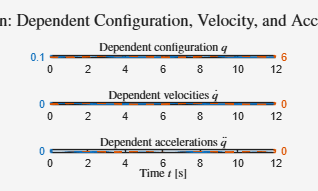


% Pulling the logged signals from the Simulink Model (To Workspace blocks).
% Squeeze function obtained from MATLAB online library. 

t_sim = out.tout;
theta2_sim = out.theta2_out;
q_sim = squeeze(out.q_out).';
qdot_sim = squeeze(out.qd_out).';
qddot_sim = squeeze(out.qdd_out).';

%%%%%%%%%%%%%%%%%%%%%%%%%%%% LAB 5B.4.6 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Three row figure showing the two components of q, qdot, and qddot against
% time

figure
theme(gcf, "light")
tl2 = tiledlayout(3,1);
title(tl2, 'Part B Simulation: Dependent Configuration, Velocity, and Acceleration vs. Time', 'Interpreter', 'latex')

nexttile
yyaxis left
plot(t_sim, q_sim(:,1), '-', 'LineWidth', 1.5)
ylabel('$r_{OB}$ [m]', 'Interpreter', 'latex')
yyaxis right
plot(t_sim, q_sim(:,2), '--', 'LineWidth', 1.5)
ylabel('$\theta_3$ [rad]', 'Interpreter', 'latex')
title('Dependent configuration $q$', 'Interpreter', 'latex')
grid on

nexttile
yyaxis left
plot(t_sim, qdot_sim(:,1), '-', 'LineWidth', 1.5)
ylabel('$\dot{r}_{OB}$ [m/s]', 'Interpreter', 'latex')
yyaxis right
plot(t_sim, qdot_sim(:,2), '--', 'LineWidth', 1.5)
ylabel('$\dot{\theta}_3$ [rad/s]', 'Interpreter', 'latex')
title('Dependent velocities $\dot{q}$', 'Interpreter', 'latex')
grid on

nexttile
yyaxis left
plot(t_sim, qddot_sim(:,1), '-', 'LineWidth', 1.5)
ylabel('$\ddot{r}_{OB}$ [m/s$^2$]', 'Interpreter', 'latex')
yyaxis right
plot(t_sim, qddot_sim(:,2), '--', 'LineWidth', 1.5)
ylabel('$\ddot{\theta}_3$ [rad/s$^2$]', 'Interpreter', 'latex')
xlabel('Time $t$ [s]', 'Interpreter', 'latex')
title('Dependent accelerations $\ddot{q}$', 'Interpreter', 'latex')
grid on

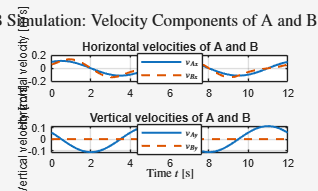


% Two row figure showing the horizontal and vertical velocity components of
% points A and B against time. Pre allocating space for Nx2 matrices for
% the velocities and then filling in the spaces with the for loop output.

vAsim = zeros(numel(t_sim),2); 
vBsim = zeros(numel(t_sim),2);
Asim = zeros(numel(t_sim),2);
Bsim = zeros(numel(t_sim),2);
aAsim = zeros(numel(t_sim),2);
aBsim = zeros(numel(t_sim),2);

for k = 1:numel(t_sim)
    [Asim(k,:),Bsim(k,:),vAsim(k,:),vBsim(k,:),aAsim(k,:),aBsim(k,:)] = crankPistonPoints( ...
        theta2_sim(k),theta2dot,q_sim(k,:).',qdot_sim(k,:).',p, ...
        theta2ddot, qddot_sim(k,:).');
end

figure
theme(gcf, "light")
tl3 = tiledlayout(2,1);
title(tl3, 'Part B Simulation: Velocity Components of A and B vs. Time', 'Interpreter', 'latex')

nexttile
plot(t_sim, vAsim(:,1), '-', t_sim, vBsim(:,1), '--', 'LineWidth', 1.5)
ylabel('Horizontal velocity [m/s]')
legend('$v_{Ax}$', '$v_{Bx}$', 'Interpreter', 'latex', 'Location', 'best')
title('Horizontal velocities of A and B')
grid on

nexttile
plot(t_sim, vAsim(:,2), '-', t_sim, vBsim(:,2), '--', 'LineWidth', 1.5)
ylabel('Vertical velocity [m/s]')
xlabel('Time $t$ [s]', 'Interpreter', 'latex')
legend('$v_{Ay}$', '$v_{By}$', 'Interpreter', 'latex', 'Location', 'best')
title('Vertical velocities of A and B')
grid on

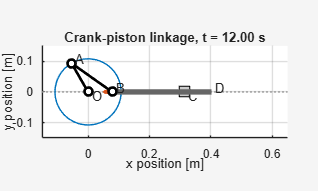


%%%%%%%%%%%%%%%%%%%%%%%%%%%% LAB 5B.4.8 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Adapting the scaled plotting approach from Part A to animate the linkage
% over two revolutions. Identifying points O, A, B, C, and D, and showing
% the paths traced by A and B. Exporting the animation as an animated GIF.

dtFrame = 0.05;                                   % frame interval [s]
t_targets = 0:dtFrame:duration;                   % desired frame times
[~, frame_indices] = min(abs(t_sim(:) - t_targets(:).'));  % nearest logged time sample to each desired time sample
frame_indices = unique(frame_indices);            % removes duplicates if solver took step longer than 0.05 s

axis_limits = [-0.15 0.65 -0.15 0.15];            % window large enough for entire motion
C = [p.r_1; 0];                                   % fixed guide at C
dLabel = 0.012;                                   % label offset [m], won't sit on marker
gifName = 'Lab5B_LinkageAnimation.gif';
Apath = [];                                       % accumulated path of A
Bpath = [];                                       % accumulated path of B

figure
theme(gcf, "light")
axis equal
axis(axis_limits)                                 % locks axes window to prevent re-scaling every frame
hold on

grid on
xlabel('x position [m]')
ylabel('y position [m]')
plot(axis_limits(1:2), [0 0], ':', 'Color', [0.6 0.6 0.6])                      % slider axis
plot(0, 0, 'ko', 'MarkerFaceColor', 'k')                                        % ground pivot O
plot(C(1), C(2), 'ks', 'MarkerSize', 10, 'MarkerFaceColor', [0.8 0.8 0.8])      % guide C
text(dLabel, -dLabel, 'O');
text(C(1)+dLabel, C(2)-dLabel, 'C');

pathA = plot(NaN, NaN, '-', 'Color', [0 0.45 0.74], 'LineWidth', 1);           % path of A
pathB = plot(NaN, NaN, '-', 'Color', [0.85 0.33 0.10], 'LineWidth', 3);        % path of B
rod   = plot(NaN, NaN, '-', 'Color', [0.4 0.4 0.4], 'LineWidth', 4);           % piston rod BD
links = plot(NaN, NaN, 'k-o', 'LineWidth', 2, 'MarkerFaceColor', 'w');         % O-A-B with joint markers
labelA = text(0, 0, 'A');
labelB = text(0, 0, 'B');
labelD = text(0, 0, 'D');
Title = title('');

for frame_index = frame_indices
    % Compute joint coordinates from the stored configuration
    [Ak, Bk] = crankPistonPoints(theta2_sim(frame_index), theta2dot, ...
        q_sim(frame_index,:).', qdot_sim(frame_index,:).', p);
    Dk = Bk + [p.r_4; 0];  % rod end D, r_4 to the right of B

    % Update the line and joint-marker graphics objects
    set(links, 'XData', [0 Ak(1) Bk(1)], 'YData', [0 Ak(2) Bk(2)])
    set(rod,   'XData', [Bk(1) Dk(1)],   'YData', [Bk(2) Dk(2)])
    labelA.Position = [Ak(1)+dLabel, Ak(2)+dLabel, 0];
    labelB.Position = [Bk(1)+dLabel, Bk(2)+dLabel, 0];
    labelD.Position = [Dk(1)+dLabel, Dk(2)+dLabel, 0];
    Title.String = sprintf('Crank-piston linkage, t = %.2f s', t_sim(frame_index));

    % Append the current A and B locations to the path graphics
    Apath = [Apath, Ak];
    Bpath = [Bpath, Bk];
    set(pathA, 'XData', Apath(1,:), 'YData', Apath(2,:))
    set(pathB, 'XData', Bpath(1,:), 'YData', Bpath(2,:))

    drawnow

    % Capture and append this frame to an animated GIF
    [img, cmap] = rgb2ind(frame2im(getframe(gcf)), 256);
    if frame_index == frame_indices(1)
        imwrite(img, cmap, gifName, 'gif', 'LoopCount', Inf, 'DelayTime', dtFrame);
    else
        imwrite(img, cmap, gifName, 'gif', 'WriteMode', 'append', 'DelayTime', dtFrame);
    end
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%% LAB 5B.4.9 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% At matching input angles, comparing the simulated dependent configurations
% with the Part A position-only results. Reporting a maximum absolute
% difference for each component, using angle wrapping where appropriate

q_partA_match = zeros(size(q_sim));
qPrev = q0;

% Same loop from part A but using simulation theta2 values to find q. Using
% previous iteration's output q as starting point for next iteration. This
% method ensures the same angle is being used for the comparison between
% the Part A match and the simulation output. 

for k = 1:numel(theta2_sim) 
    q_partA_match(k,:) = fsolve(@(q) crankPistonResidual(q,theta2_sim(k),p), ...
        qPrev, options).';
    qPrev = q_partA_match(k,:).';
end

qDifference = q_sim - q_partA_match;
qDifference(:,2) = wrapToPi(qDifference(:,2));

maxAbsDifference = max(abs(qDifference), [], 1)

maxAbsDifference = 1.0e-05 *

    0.0997    0.4418


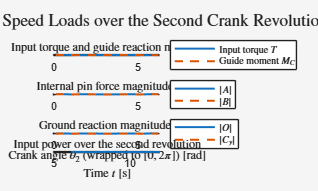


%%%%%%%%%%%%%%%%%%%%%%%%%%%% LAB 5C.4.2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Using part B joint positions and accelerations with Equation 5C.2 to
% determine COM Kinematics. Using the simulated angle, angular velocity,
% and angular acceleration for each rotating body. 

Nt = numel(t_sim);

G2_sim = Asim/2;
G3_sim = (Asim + Bsim)/2;
G4_sim = [Bsim(:,1) + p.r_4/2 , zeros(Nt,1)];
aG2_sim = aAsim/2;
aG3_sim = (aAsim + aBsim)/2;
aG4_sim = [aBsim(:,1), zeros(Nt,1)];

theta3_sim = q_sim(:,2);
theta3dot_sim = qdot_sim(:,2);
theta3ddot_sim = qddot_sim(:,2);

%%%%%%%%%%%%%%%%%%%%%%%%%%%% LAB 5C.4.4 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Use simulation values and the loadRecovery function to populate the 
% Y array, filled with ordered load vectors at each time interval, 
% and turn the array into a table. 

Y = zeros(Nt,9);
for k = 1:Nt
    Y(k,:) = loadRecovery(theta2_sim(k), theta3_sim(k), theta2ddot, theta3ddot_sim(k), ...
    aG2_sim(k,:).', aG3_sim(k,:).', aG4_sim(k,1), q_sim(k,1), p).';
end

loads = array2table(Y, 'VariableNames', ...
    {'Ox','Oy','Ax','Ay','Bx','By','Cy','Mc','T'});

%%%%%%%%%%%%%%%%%%%%%%%%%%%% LAB 5C.4.6 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Plotting nominal speed loads over the second crank revolution. Isolating
% the time values associated with the second revolution, then isolating
% array values associated with the second revolution. Wrapping the second
% revolution input crank angles to the 0-2*pi range, adding these to the table, and
% sorting the table from smallest to largest theta2 values. Calculating pin
% and ground force magnitudes, as well as the input power. 

T_rev = 2*pi/abs(theta2dot); % period for one revolution (s) 
t_all = t_sim(:); % force t_sim into a column vector to line up with loads array
th_all = theta2_sim(:); % force theta2_sim into a column vector to line up with loads array
rev2 = t_all >= T_rev; % isolating the rows corresponding to the second rev only 

L = loads(rev2,:);
L.theta2 = mod(th_all(rev2), 2*pi); % wraps all the second rev angles into the 0 -> 2*pi range, 
                                   % adds a column to the table
L = sortrows(L, 'theta2'); % reorders the array rows from smallest theta2 to largest - fixes wrap jump                             
th2_plot = L.theta2; % theta2 values for plots                                 

A_mag = hypot(L.Ax, L.Ay); % Magnitude of pin force at A
B_mag = hypot(L.Bx, L.By); % Magnitude of pin force at B
O_mag = hypot(L.Ox, L.Oy); % Magnitude of pin force at O
C_mag = abs(L.Cy); % Magnitude of pin force at C

t_rev2 = t_all(rev2); % time values corresponding to second rev only
P_in = loads.T(rev2) * theta2dot; % Power in = T * theta2dot [W]

figure
theme(gcf, "light")
tl4 = tiledlayout(4,1);
title(tl4, 'Part C: Nominal Speed Loads over the Second Crank Revolution', 'Interpreter', 'latex')

% Input torque and guide reaction moment vs. crank angle
nexttile
plot(th2_plot, L.T, '-', 'LineWidth', 1.5)
hold on
plot(th2_plot, L.Mc, '--', 'LineWidth', 1.5)
hold off
ylabel('Moment [N$\cdot$m]', 'Interpreter', 'latex')
legend('Input torque $T$', 'Guide moment $M_C$', 'Interpreter', 'latex', 'Location', 'eastoutside')
title('Input torque and guide reaction moment', 'Interpreter', 'latex')
xlim([0 2*pi]); 
grid on

% Pin reaction magnitudes vs. crank angle
nexttile
plot(th2_plot, A_mag, '-',  'LineWidth', 1.5)
hold on
plot(th2_plot, B_mag, '--', 'LineWidth', 1.5)
hold off
ylabel('Force [N]', 'Interpreter', 'latex')
legend('$|A|$', '$|B|$', 'Interpreter', 'latex', 'Location', 'eastoutside')
title('Internal pin force magnitudes', 'Interpreter', 'latex')
xlim([0 2*pi]); 
grid on

% Ground reaction magnitudes vs. crank angle
nexttile
plot(th2_plot, O_mag, '-',  'LineWidth', 1.5)
hold on
plot(th2_plot, C_mag, '--', 'LineWidth', 1.5)
hold off
ylabel('Force [N]', 'Interpreter', 'latex')
xlabel('Crank angle $\theta_2$ (wrapped to $[0, 2\pi]$) [rad]', 'Interpreter', 'latex')
legend('$|O|$', '$|C_y|$', 'Interpreter', 'latex', 'Location', 'eastoutside')
title('Ground reaction magnitudes', 'Interpreter', 'latex')
xlim([0 2*pi]); grid on

% Input power vs. time
nexttile
plot(t_rev2, P_in, '-', 'LineWidth', 1.5)                      
ylabel('Input power $P_{in}$ [W]', 'Interpreter', 'latex')
xlabel('Time $t$ [s]', 'Interpreter', 'latex')
title('Input power over the second revolution', 'Interpreter', 'latex')
grid on

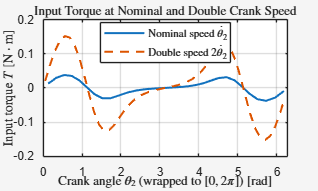


%%%%%%%%%%%%%%%%%%%%%%%%%%%% LAB 5C.4.7 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Speed-squared scaling: rerunning the kinematics and load recovery for one
% revolution, at twice the normal crank speed, from the same starting
% configuration q0. Simulink reads theta2dot and q0dot from the workspace,
% so here they are temporarily set to the double-speed values and restored
% after. 

theta2dot_nom = theta2dot; % save nominal value
q0dot_nom = q0dot; % save nominal value

theta2dot = 2*theta2dot_nom; % double crank speed [rad/s]
q0dot = crankPistonKinematics(theta2,theta2dot,theta2ddot,q0,p);
duration_double = 2*pi/abs(theta2dot); % one revolution at double speed [s]

out2 = sim(modelName, ...
    'StopTime', num2str(duration_double), ...
    'Solver', solver, ...
    'RelTol', num2str(relTol), ...
    'AbsTol', num2str(absTol));

% Extract and compare the double-speed loads over one revolution
t_double = out2.tout;
theta2_double = out2.theta2_out;
q_double = squeeze(out2.q_out).';
qdot_double = squeeze(out2.qd_out).';
qddot_double = squeeze(out2.qdd_out).';

% Joint accelerations at double speed, same as nominal speed loop
Nt2 = numel(t_double);
aAsim2 = zeros(Nt2,2);
aBsim2 = zeros(Nt2,2);

for k = 1:Nt2
    [~,~,~,~,aAsim2(k,:),aBsim2(k,:)] = crankPistonPoints(theta2_double(k), theta2dot, ...
        q_double(k,:).', qdot_double(k,:).', p, theta2ddot, qddot_double(k,:).');
end 

% C.O.M. accelerations
aG2_sim2 = aAsim2/2;
aG3_sim2 = (aAsim2 + aBsim2)/2;
aG4_sim2 = [aBsim2(:,1), zeros(Nt2,1)];

theta3_double = q_double(:,2);
theta3ddot_double = qddot_double(:,2);
r_ob_double = q_double(:,1);

% allocate space for Y2 array
Y2 = zeros(Nt2,9);

for k = 1:Nt2
    Y2(k,:) = loadRecovery(theta2_double(k), theta3_double(k), theta2ddot, theta3ddot_double(k), ...
        aG2_sim2(k,:).', aG3_sim2(k,:).', aG4_sim2(k,1), r_ob_double(k), p).';
end

loads2 = array2table(Y2, 'VariableNames', ...
    {'Ox','Oy','Ax','Ay','Bx','By','Cy','Mc','T'});

% restore nominal values
theta2dot = theta2dot_nom;
q0dot = q0dot_nom;

% Double=speed loads sorted and wrapped the same way as the nominal-speed
% loads
L2 = loads2;
L2.theta2 = mod(theta2_double, 2*pi);
L2 = sortrows(L2, 'theta2');

% Overlay plot: nominal-speed (2nd rev) vs. double-speed torque 
figure
theme(gcf, "light")
plot(th2_plot,  L.T,  '-',  'LineWidth', 1.5)
hold on
plot(L2.theta2, L2.T, '--', 'LineWidth', 1.5)
hold off
xlabel('Crank angle $\theta_2$ (wrapped to $[0, 2\pi]$) [rad]', 'Interpreter', 'latex')
ylabel('Input torque $T$ [N$\cdot$m]', 'Interpreter', 'latex')
legend('Nominal speed $\dot{\theta}_2$', 'Double speed $2\dot{\theta}_2$', ...
    'Interpreter', 'latex', 'Location', 'best')
title('Input Torque at Nominal and Double Crank Speed', 'Interpreter', 'latex')
xlim([0 2*pi]); 
grid on



%%%%%%%%%%%%%%%%%%%%%%%%%%%% FUNCTIONS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% crankPistonResidual checks connection of guessed linkage shape. Returns how 
% far off the guess is (phi) and which way to adjust it (J). fsolve keeps feeding 
% it better guesses until the gap closes to zero.

function [phi,J] = crankPistonResidual(q,theta2,p)
% q = [r_ob; theta3] with length in m and angle in rad

r_ob = q(1);
theta3 = q(2);

phi = [p.r_2*cos(theta2) + p.r_3*cos(theta3) - r_ob;
       p.r_2*sin(theta2) + p.r_3*sin(theta3)];

J = [-1, -p.r_3*sin(theta3);
      0, p.r_3*cos(theta3)];

end
%%%%%%%%%%%%%%%%%%%%%

% crankPistonKinematics solves the kinematic equations developed in Pre Labs 5A and 5B.
% Uses matrix arithmetic and derived velocity and acceleration models to obtain
% qdot = [r_ob_dot;theta3dot] and qddot = [r_ob_ddot;theta3ddot].

function [qdot,qddot,J,bv,ba] = crankPistonKinematics(theta2,theta2dot,theta2ddot,q,p)

r_ob = q(1);
theta3 = q(2);

J = [-1, -p.r_3*sin(theta3);
     0,  p.r_3*cos(theta3)];

bv = [p.r_2*sin(theta2)*theta2dot;
     -p.r_2*cos(theta2)*theta2dot];

qdot = J \ bv;

r_ob_dot = qdot(1);
theta3dot = qdot(2);

ba = [p.r_2*cos(theta2)*theta2dot^2 + p.r_2*sin(theta2)*theta2ddot + ...
      p.r_3*cos(theta3)*theta3dot^2;
      p.r_2*sin(theta2)*theta2dot^2 - p.r_2*cos(theta2)*theta2ddot + ...
      p.r_3*sin(theta3)*theta3dot^2];

qddot = J \ ba;

end
%%%%%%%%%%%%%%%%%%%%%

% crankPistonPoints Locates joints A and B by adding up the crank and coupler 
% vectors from point O. Then differentiates these vectors to get each
% joint's velocity, and will differentiate a second time to get the joint
% accelerations when requested. 

function [A,B,vA,vB,aA,aB] = crankPistonPoints(theta2,theta2dot,q,qdot,p, theta2ddot, qddot)

theta3 = q(2);
theta3dot = qdot(2);

A  = p.r_2*[cos(theta2); sin(theta2)];                 % O -> A
B  = A + p.r_3*[cos(theta3); sin(theta3)];             % O -> A -> B
vA = p.r_2*theta2dot*[-sin(theta2); cos(theta2)];      % d/dt of O -> A
vB = vA + p.r_3*theta3dot*[-sin(theta3); cos(theta3)]; % d/dt of O -> A -> B

% Found nargout in Matlab online library. nargout is the number of inputs
% called for. Since earlier calls of this function request 4 or fewer
% outputs, this acceleration block is skipped. Calls that request aA and aB
% will run this code and must pass in aA and aB.

if nargout > 4 
    theta3ddot = qddot(2);

    aA = p.r_2*theta2ddot*[-sin(theta2); cos(theta2)]...
        - p.r_2*theta2dot^2*[cos(theta2); sin(theta2)];
    aB = aA + p.r_3*theta3ddot*[-sin(theta3); cos(theta3)]...
        - p.r_3*theta3dot^2*[cos(theta3); sin(theta3)];
end

end
%%%%%%%%%%%%%%%%%%%%%

% qdd evaluates J and ba at the current input, configuration, and dependent
% velocity, and then returns qdd = J \ ba.

function qdd = linkageAcceleration(u,ud,udd,q,qd,p)
% u = theta2, ud = theta2dot, udd = theta2ddot
% q = [r_ob; theta3], qd = [r_ob_dot, theta3dot]
theta3 = q(2);
theta3dot = qd(2);

J = [-1, -p.r_3*sin(theta3);
      0, p.r_3*cos(theta3)];

ba = [p.r_2*cos(u)*ud^2 + p.r_2*sin(u)*udd + p.r_3*cos(theta3)*theta3dot^2;
      p.r_2*sin(u)*ud^2 - p.r_2*cos(u)*udd + p.r_3*sin(theta3)*theta3dot^2];

qdd = J \ ba;

end
%%%%%%%%%%%%%%%%%%%%%

% loadRecovery accepts one configuration's geometry and kinematics, forms K and d in
% Equation 5C.5, and returns the ordered load vector y = K \ d

function y = loadRecovery(theta2,theta3,theta2ddot,theta3ddot,aG2,aG3,aG4x,r_ob,p)

    c2 = cos(theta2);  s2 = sin(theta2);
    c3 = cos(theta3);  s3 = sin(theta3);

    %   Ox           Oy           Ax           Ay           Bx           By         Cy                   MC  T
    K = [ 1          0            1            0            0            0           0                    0   0;   % (1) crank sum Fx
        0            1            0            1            0            0           0                    0   0;   % (2) crank sum Fy
        p.r_2/2*s2  -p.r_2/2*c2  -p.r_2/2*s2   p.r_2/2*c2   0            0           0                    0   1;   % (3) crank sum M_G2
        0            0           -1            0            1            0           0                    0   0;   % (4) coupler sum Fx
        0            0            0           -1            0            1           0                    0   0;   % (5) coupler sum Fy
        0            0           -p.r_3/2*s3   p.r_3/2*c3  -p.r_3/2*s3   p.r_3/2*c3  0                    0   0;   % (6) coupler sum M_G3
        0            0            0            0           -1            0           0                    0   0;   % (7) rod sum Fx
        0            0            0            0            0           -1           1                    0   0;   % (8) rod sum Fy
        0            0            0            0            0            p.r_4/2     p.r_1-r_ob-p.r_4/2   1   0 ]; % (9) rod sum M_G4

    d = [ p.m_2*aG2(1);        % (1) m2 * xddot_G2
        p.m_2*aG2(2);          % (2) m2 * yddot_G2
        p.I_2*theta2ddot;      % (3) I2 * theta2ddot
        p.m_3*aG3(1);          % (4) m3 * xddot_G3
        p.m_3*aG3(2);          % (5) m3 * yddot_G3
        p.I_3*theta3ddot;      % (6) I3 * theta3ddot
        p.m_4*aG4x;            % (7) m4 * xddot_G4
        0;                     % (8) no rod vertical acceleration
        0 ];                   % (9) no rod rotation

    y = K \ d;

end
%%%%%%%%%%%%%%%%%%%%%








